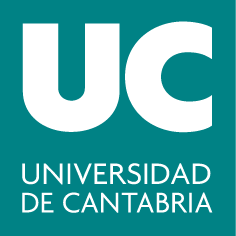

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Cálculo I**

# **1. Introducción a MATLAB**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

### ¿Qué es MATLAB?

[MATLAB](https://www.mathworks.com) es un lenguaje de programación de alto nivel enfocado inicialmente al cálculo numérico. Por lo tanto, tiene diversas herramientas para el cálculo matricial y la resolución numérica de problemas lineales y no lineales. Del mismo modo, presenta diferentes herramientas gráficas para visualizar los resultados obtenidos. Se puede utilizar a través de su línea de comandoso mediante la interfaz de usuario.

MATLAB es un programa comercial y cerrado, que requiere el pago de una licencia. La Universidad de Cantabria tiene licencia en las aulas de informática de la EPIME y también puede instalarse en los ordenadores personales siguiendo [estas instrucciones](https://sdei.unican.es/Paginas/servicios/software/Matlab-Campus.aspx) y el usuario de la UC.

El nombre de MATLAB es un acrónimo de MATrix LABoratory. Hoy en día Matlab es un programa muy potente con un entorno agradable, que incluye herramientas de visualización gráfica, así como un lenguaje de alto nivel.

Se pueden consultar manuales en la [web oficial](https://www.mathworks.com).

### Empezando a usar MATLAB

La ventana de MATLAB muestra un escritorio dividido en varias partes, entre ellas:

- Las órdenes a ejecutar se escriben en la ventana de comandos, `Command Window`.

- En el editor (ventana `Editor`) escribimos código que guardaremos en scripts con extensión `.m` y ejecutaremos en la ventana de comandos. 

- La ventana `Workspace` proporciona información sobre las variables utilizadas.

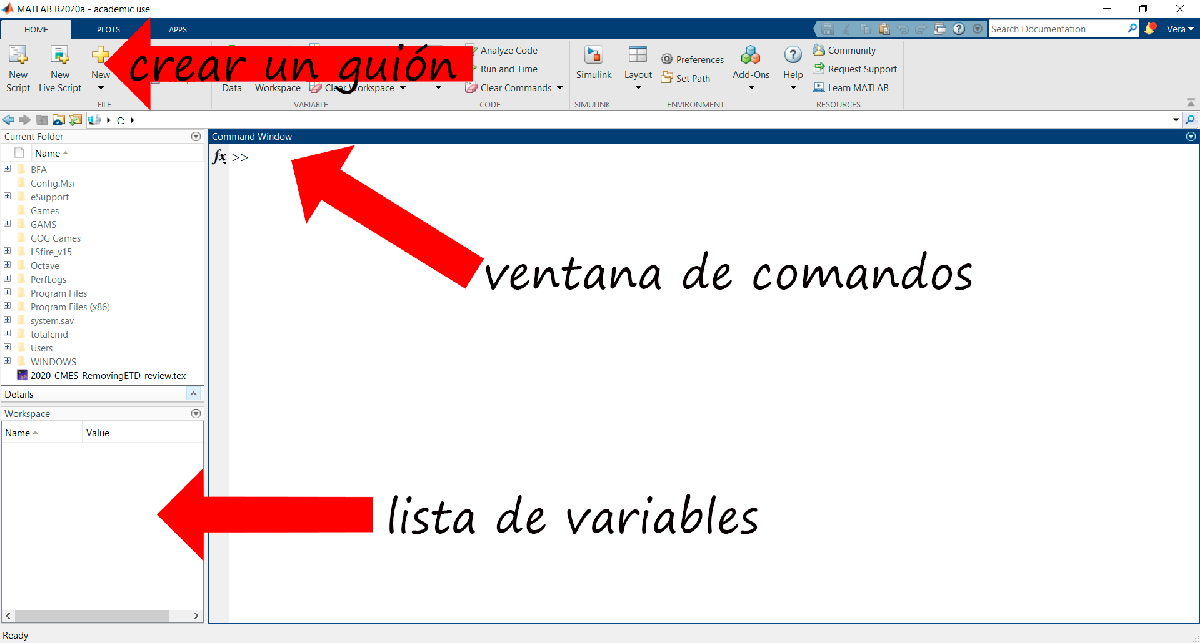

Aunque hay más, los tipos de datos básicos en MATLAB para nosotros son los siguientes: números reales o complejos, booleanos (valores lógicos) y cadenas de caracteres (o `strings`). En cualquier caso, el objeto básico de trabajo en MATLAB son las matrices. Los escalares y los vectores son considerados casos particulares de matrices.

**Uso de la ventana de comandos**

Las instrucciones que terminan por punto y coma no producen salida de resultados por pantalla. Se pueden recuperar instrucciones anteriores, usando las teclas de flechas arriba y abajo.

### Variables

Para crear una nueva variable con la que trabajar, se especifica el nombre que se le quiere dar a dicha variable, seguido del signo igual "`=" `(operador de asignación) y el valor que se le desea asignar.

Hay ciertas **reglas para definir variables en MATLAB**:

- No se pueden crear variables sin asignarles un valor. 

- El nombre de una variable puede tener como máximo 63 caracteres que pueden ser letras, números y el guion de subrayar.

- El primer carácter tiene que ser una letra, matriz2 es un nombre válido, pero no lo es 2matriz.

- Las mayúsculas y las minúsculas tienen valor distintivo. La variable Modulo es distinta de la variable modulo. 

- Dentro de un nombre de variable no puede haber espacios en blanco, modulo1  es un nombre de variable válido, pero no  modulo 1.

- Existen nombres que deben evitarse porque tienen significado propio en Matlab: ans, pi, Inf, i, . . .

Pi = pi

Ahora pulsa 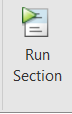 para ejecutar el código.Aparece el resultado: hemos creado una variable `Pi` que tiene el valor 3.1416. También la variable aparece en el espacio de trabajo (Workspace):

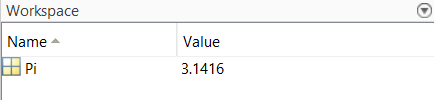

A tener en cuenta:

- Al abrir sesión seleccionaremos el **directorio de trabajo**, donde almacenaremos los scripts.

- Si se escribe `;` al final de una linea de código, no se  muestra el resultado por pantalla. Esta característica es la deseada cuando se trabaja con grandes conjuntos de datos:

a = 1; % Se crea una variable a con valor 1, pero no se imprime el resultado
b = 2  % Se imprime el resultado (b = 2)

- **Obtener ayuda** en Matlab: El comando `help` es la orden  básica de ayuda con la cual consultar el uso de una  función, incluyendo los argumentos de entrada/salida, una breve  descripción de qué realiza y de su uso.

help pi

- Se pueden incluir **comentarios** (aclaraciones que no se ejecutan) dentro de los programas añadiendo `%` delante de lo que se desea comentar.

% help pi

- Se puede **ejecutar** un programa entero pulsando la tecla "Run", o bien una(s) línea(s) seleccionadas pulsando F9 o seleccionando "Evaluate selection" en el menú que sale al pinchar con el botón derecho del ratón.

- Es **esencial leer los errores** que obtenemos cuando algo no funciona, ya que contienen información acerca del error. Además, la(s) línea(s) afectada(s) tiene una señal roja a la derecha del editor.

a1 = 1; % Ok
% Descomenta la siguiente línea (Elimina el símbolo de comentario %) y observa qué sucede:
%1a = 1 % No está bien, Matlab da la explicación (y a veces ofrece una solución)

**Ejercicio:** Corrige el error en el código anterior (Pulsa "Fix").  Descomenta las siguentes líneas del código y corrige los errores:

% 1a = 1;
% valor 1 = pi
% x = % 5 

#### Tipos de datos

MATLAB trabaja con los tipos básicos de datos (números, caracteres y  booleanos) a partir de los cuales se construyen vectores, matrices,  cadenas de caracteres, etc. Del mismo modo, a partir del tipo de datos se definen diferentes operaciones básicas (suma, producto, intersecciones, etc.) que permiten la construcción y definición por composición de operaciones complejas.

Además de los tipos de datos básicos existen diferentes tipos de  variables que sirven de contenedores de datos, como son el tipo `cell`, `struct` o variables simbólicas (`sym`).

Para saber qué variables están definidas y a que tipo de datos corresponde tenemos el comando `whos:`

whos

Compara con el contenido de la ventana `Workspace`. Como mencionamos anteriormente, los escalares son un caso particular de matrices; tienen un tamaño de 1x1, lo que significa que son matrices con una fila y una columna.

### Comandos básicos

#### Cabecera de un programa

% Limpia el espacio de trabajo
clear all % se recomienda usar 'clearvars' para borrar las variables
% Limpia la ventana de comandos
clc
% Cierra las ventanas/figuras abiertas
close all
% Lista las variables definidas en el espacio de trabajo
whos 

#### Operaciones básicas

La forma de representar números y de operar con Matlab es la misma que  la de una calculadora de bolsillo, usando las operaciones `+, -, *, /, ^`. Se recomienda **siempre asignar el resultado a una variable**. Si no asignas el resultado a una variable, Matlab lo almacena temporalmente en la variable predeterminada `ans`, pero esto puede llevar a errores y confusión, especialmente en scripts más complejos.

suma = 17+5 %Suma
division = 17/5 %Division con decimales

#### Funciones matemáticas elementales

- `exp(x)`: exponencial de x

- `log(x)`: logaritmo natural o neperiano.

- `log10(x)`: logaritmo en base 10.

- `sin(x)`: seno de x.

- `cos(x)`: coseno de x.

- `tan(x)`: tangente de x.

- `asin(x)`: arco seno de x con imagen en el rango $[-\pi/2, \pi/2]$.

- `acos(x)`: arco coseno de x con imagen en el rango $[-\pi/2, \pi/2]$.

- `atan(x)`: arco tangente de x con imagen en el rango $[-\pi/2, \pi/2]$.

- `atan2(y,x)`: arco tangente de y/x con imagen en el rango $[-\pi, \pi]$.

- `sinh(x)`: seno hiperbólico de x.

- `cosh(x)`: coseno hiperbólico de x.

- `tanh(x)`: tangente hiperbólica de x.

- `sum(x)`: suma de los elementos del vector x.

- `prod(x)`: producto de los elementos del vector x.

**Importante: **en estas funciones el ángulo viene en radianes:

c = cos(pi) % no 'cos(180)' para calcular el coseno de pi (de 180 grados)
a = 4*atan(1) %atan: Funcion arcotangente con resultado en radianes. 
% Se guarda el resultado en la variable a
s = sin(pi/2) %Seno de pi/2
l = log(exp(1)^5) %Función logaritmo natural

Jerarquia de las operaciones: multiplicacion y division, suma y resta:

b1 = 1+2*3 
b2 = (1+2)*3 %Uso del parentesis

#### Formatos

Podemos cambiar la forma en la que MATLAB muestra por pantalla los números mediante el comando `format`:

format short, 1/3  % 4 decimales
format long, 1/3  % 15 decimales
format longe, 1/3  % Notación científica larga 
format rat, 1/3  % fraccion

Sin embargo, hay que tener en cuenta que el cambio de formato sólo tiene efecto a nivel de visualización (el número con el que MATLAB trabaja en memoria seguirá siendo siempre el mismo).

format short

### **Matrices y vectores**

#### **Crear y manipular vectores**

Hay varias maneras de construir vectores fila:

u=[-7,3,4,-2] %Corchetes y comas
v=[-7 3 4 -2] %Corchetes sin comas   
t= 1:3:20 % para crear secuencias de números tomados de tres en tres, 
% tales que inicial:incremento:final 
z= linspace(1,2,9) % genera un vector fila de 9 elementos cuyo primer elemento 
% es 1 y el último 2, siendo todos sus elementos equidistantes: 
% linspace(inicial, final, n)

Y vectores columna:

w=[-7;3;4;-2] %Vector vertical
x= u' % Trasponiendo un vector fila

Se puede comprobar el tamaño de los vectores y extraer elementos:

lu = length(u) %Numero de elementos del vector
lw = length(w) 
su = size(u) %Numero de filas y columnas

u(1) %Primer elemento del vector u
w(4) %Cuarto elemento del vector w
u(1)=-4 %Cambia el elemento 1 del vector u

#### Crear y manipular matrices

A=[3,-7;2,5] %Corchetes y comas. Definida por filas
B=[3 -7; 2 5] %Corchetes sin comas
C=[6 0 -3 8 9; 5 1 7 -4 2; 3 1 -6 2 -1]
C(2, 3) %Elemento de la fila 2 y columna 3 de la matriz c
size(C) %Numero de filas y columnas de la matriz c
length(C) %Numero de columnas de la matriz c
C(1, 4)=11 %Cambio del elemento de la fila 1 y 4 columna de la matriz c

#### Matrices especiales

Son aquellas formadas por ceros, unos o la identidad.

zeros(3,5) %Nula de 3 filas y 5 columnas
zeros(4) %Nula 4x4
ones(2,4) %Unidad de 2 filas y 4 columnas
ones(3) %Unidad 3x3
eye(4) % Matriz identidad de ornden 4 (i.e. diagonal de 1 4x4)
A = diag([-7 2 4]) %Diagonal con los valores dados

#### Submatrices

Se pueden extraer submatrices de una matriz mayor indicando la fila o columna que se desea. `:` indica todos los elementos.

A=[6 0 -3 8 9; 5 1 7 -4 2; 3 1 -6 2 -1] %Define matriz
A(2, :) %Fila 2 de la matriz a
A(:, 5) %Columna 5 de la matriz a
A(3, :)= -7 %Cambia todos los elementos de la fila 3 por -7

#### Operaciones con matrices

Cuando trabajamos con matriz, para operar elemento a elemento hay que usar los comandos:` .*, ./, .^`, ya que el producto de matrices como tal no está definido elemento a elemento.

A=[-3 7; 2 5] %Define matriz
A+100 %Suma 100 a cada elemento de la matriz. % Igual para restas, multiplicaciones y divisiones
A=[-3 4 2; 1 7 -5] %Define matriz
B=[1 -2 -9; 4 2 6] %Define matriz
C=A+B % guarda el resultado en la variable c
A+B %Opera sin almacenar
0.3*A %Multiplica todos los valores de a por 0.3
C=A.*B %Multiplica matrices elemento a elemento

#### Comandos sum y prod

- El comando `sum`  se utiliza para calcular la suma de los elementos de un vector o matriz.

- El comando `prod` se utiliza para calcular el producto de los elementos de un vector o matriz.

**Notas:**

- Los comandos `sum` y `prod` se pueden aplicar a matrices y vectores.

- Cuando se usa en una matriz sin especificar la dimensión,  los comandos operan por columnas.

- Para sumar los elementos de cada fila, usa `sum(M, 2)`.

- Para obtener el producto de los elementos de cada fila, usa `prod(M, 2)`.

M = [1, 2, 3; 
     4, 5, 6; 
     7, 8, 9];
suma_columnas = sum(M) % suma_columnas  [12, 15, 18]
suma_filas = sum(M, 2) % Calcula la suma de los elementos en cada fila

**Ejericicio**: Calcula suma de todos los elemntos de la matriz M.

% Escribe aquí el código:



### Ejercicios resueltos

a) Calcula la suma de los primeros 100 números naturales.

b) Calcula la suma de los cubos de los primeros 100 números naturales.

c) Calcula la suma de todos los números pares de 3 cifras y la suma de sus cuadrados.

d) Calcula el producto de las raíces cuadradas de los primeros 5 números naturales.

e) Calcula $\left(3^{\cos \;\frac{\pi }{4}} -2e^2 \right)\sqrt{\ln \;5}$

a) Calcula la suma de los primeros 100 números naturales.

k=1:100; % crea un vector con los números de 1 al 100.
suma=sum(k) % suma los elementos de k y guarda el resultado en la variable suma.

b) Calcula la suma de los cubos de los primeros 100 números naturales.

k3=k.^3; % eleva al cubo cada elemento del vector k
suma=sum(k3) % suma los elementos de k3

c) Calcula la suma de todos los números pares de 3 cifras y la suma de sus cuadrados.

pares=100:2:998; % crea el vector de números pares de 3 cifras
suma=sum(pares) % suma los elementos del vector pares
suma_cuadrados=sum(pares.^2) % suma de los cuadrados de pares

d) Calcula el producto de las raíces cuadradas de los primeros 5 números naturales.

a=1:5; % vector formado por los primeros 5 números naturales
raiz=sqrt(a); % calcula la raíz cuadrada de los elementos de a
prducto=prod(raiz) % calcula la suma de las raíces cuadrada

e) Calcula $\left(3^{\cos \;\frac{\pi }{4}} -2e^2 \right)\sqrt{\ln \;5}$

% por partes:
a1 = 3^(cos (pi/4) ) 
a2 = 2*exp(2)
a3 = sqrt( log(5) )
res = (a1-a2)*a3

% directamente en una línea:
res = ( 3^(cos (pi/4) ) - 2*exp(2) )*sqrt( log(5) )

### Ejercicios propuestos

- Calcula la suma de las raíces cúbicas de los primeros 50 números naturales.

- Calcula el producto de los cuadrados de todos los números impares de dos cifras.

- Calcula: 

 
$$a = \left(\sqrt{6} - 3\right)\left(3 + 2^{1/2} \cdot 3^{0.5}\right)\\
b= \; \cos (3\pi) + 12 \,sen\, \frac{3\pi}{2}\\
c = \; e^{4-8^{2/3}}$$


% Escribe aquí el código:









Compara tus resultados con las soluciones:

soluciones() 

### Resumen

**Ventana de MATLAB**

- `Command Window`: Donde se escriben y ejecutan las órdenes.

- `Editor`: Donde se escribe y guarda el código en scripts `.m`.

- `Workspace`: Muestra las variables utilizadas.

**Variables y Tipos de Datos**

- Crear variables: `nombre = valor`

- Reglas para nombres de variables: Hasta 63 caracteres, comenzando con una letra, sin espacios, distinguibles entre mayúsculas y minúsculas.

**Comandos Básicos**

-  [`clear`](https://es.mathworks.com/help/matlab/ref/clear.html)` all/ clearvars`: Limpia el espacio de trabajo.

-[ `clc`](https://es.mathworks.com/help/matlab/ref/clc.html): Limpia la ventana de comandos.

- [`close`](https://es.mathworks.com/help/matlab/ref/close.html)` all`: Cierra figuras abiertas.

- [`whos`](https://es.mathworks.com/help/matlab/ref/whos.html): Lista las variables definidas.

- Operaciones básicas: Suma: `+`, Resta: `-`, Multiplicación: `*`, División: `/`, Potencia: `^`

- [Funciones matemáticas elementales](https://es.mathworks.com/help/matlab/elementary-math.html):  `exp(x), log(x), sin(x), cos(x), tan(x)`, etc.

- [`format`](https://es.mathworks.com/help/matlab/ref/format.html#btiwmh5-3)` short`: Muestra 4 decimales (long: Muestra 15 decimales; longe: Notación científica larga; rat: Muestra como fracción)

**Matrices y Vectores**

- Crear vectores:

      - Filas: `u=[-7,3,4,-2]` o `v=[-7 3 4 -2]`

      - Columnas: `w=[-7;3;4;-2]`

      - Secuencias: `t=1:3:20`, `z=linspace(1,2,9)`

- Crear matrices: `A=[3,-7;2,5]`

- [Operaciones con matrices](https://es.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html?searchHighlight=suma%20resta&s_tid=srchtitle_support_results_2_suma%20resta): `C=A+B`, `C=A.*B`

- [`length(v)`](https://es.mathworks.com/help/matlab/ref/length.html)`: `Longitud del vector

- [`size(A)`](https://es.mathworks.com/help/matlab/ref/size.html)`: `Tamaño de la matriz

- [`sum(A)`](https://es.mathworks.com/help/matlab/ref/sum.html)`: `Calcular la suma de los elementos en un vector o matriz

- [`prod(A)`](https://es.mathworks.com/help/matlab/ref/prod.html)`: `Producto de los elementos en un vector o matriz

- [Matrices especiales](https://es.mathworks.com/help/matlab/matlab_oop/class-support-for-array-creation-functions.html):  `zeros(3,5), ones(2,4), eye(4), diag([-7 2 4])`

- Extraer filas/columnas: `A(2,:), A(:,5)`

- Modificar elementos: `A(3,:)= -7`

**Ayuda y Depuración**

- Obtener ayuda: [`help`](https://es.mathworks.com/help/matlab/ref/help.html)` function_name`

- Comentarios: Usar `%` para incluir comentarios en el código.

- Ejecutar el código: "Run", "F9", o "Run Section".

### Soluciones 

function [] = soluciones()

% Ejercicio 1:
k=1:50;
raices=k.^(1/3);
s1=sum(raices);
fprintf("Soluciones:\nEjercicio 1:\n S1 = %.4f\n",s1);

% Ejercicio 2:
k=11:2:99;
cuadrados = k.^2;
s2=prod(cuadrados);
fprintf("Ejercicio 2:\n S2 = %d\n",s2);

% Ejercicio 3
a = (sqrt(6) - 3)*(3 + 2^(1/2) * 3^(0.5));
b = cos(3*pi) + 12*sin(3*pi/2);
c = exp(4-8^(2/3));
fprintf("Ejercicio 3:\n a = %.0f\n b = %0.f\n c = %.0f\n",a,b,c);
end